clear; close all
% Load the model and apply the corrections for *all* models
model902 = loadYeastModel;
cd('../modelCuration/')
v9_1_0;

Identifier of new metabolite "sulphate[m]": s_4333
Identifier of new reaction "oxaloacetate/sulphate antiport, mitochondrial": r_4783
Identifier of new reaction "malate/sulphate antiport, mitochondrial": r_4784
Current biomass adds up to 0.9949 g/g. Protein fraction is scaled from 0.4597 to 0.4648 g/g to reach 1 g/g total biomass.
P -> 0.46483 g/gDW
C -> 0.38311 g/gDW
R -> 0.054138 g/gDW
D -> 0.0032743 g/gDW
L -> 0.087299 g/gDW
I -> 0.002504 g/gDW
F -> 0.0048504 g/gDW
X -> 1 gDW/gDW
Growth = 0.084532 1/h
 


## Run growth tests

Use the 9.1.0 model with the new anaerobic script, this should be the best model.

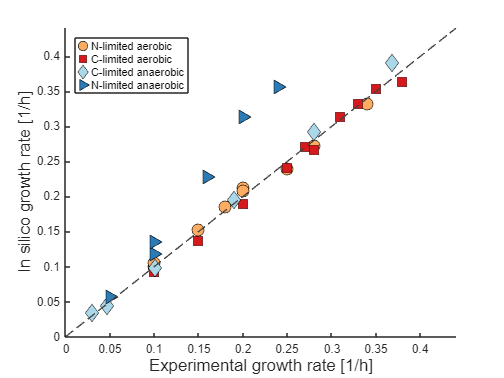

R2 in 9.1.0 model with new anaerobic script: 0.9077


R2new = growth(model); fprintf("R2 in 9.1.0 model with new anaerobic script: %.4f\n", R2new)

Use the 9.1.0 model, but use the old `anaerobicModel` script. [Note that this is not *exactly* the old `anaerobicModel` script, it has been curated to prevent the curation of protein-content in nitrogen limiting conditions to be overwritten in anaerobic conditions].

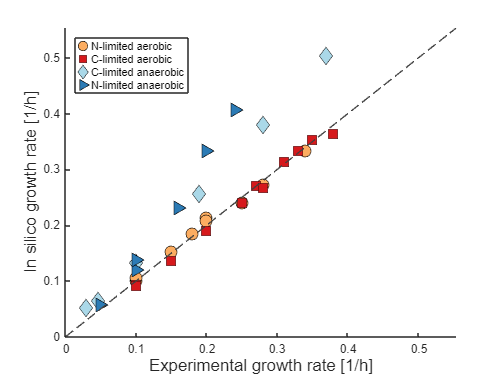

R2 in 9.1.0 model with old anaerobic script: 0.8314


R2old = growthOld(model); fprintf("R2 in 9.1.0 model with old anaerobic script: %.4f\n", R2old)

Did the generic curation have much influence? Repeat the two curves (with new and old `anaerobicModel` script) with the 9.0.2 model.

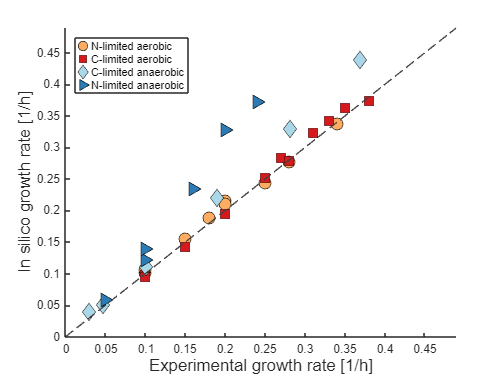

R2 in 9.1.0 model with new anaerobic script: 0.8985


R2new902 = growth(model902); fprintf("R2 in 9.1.0 model with new anaerobic script: %.4f\n", R2new902)

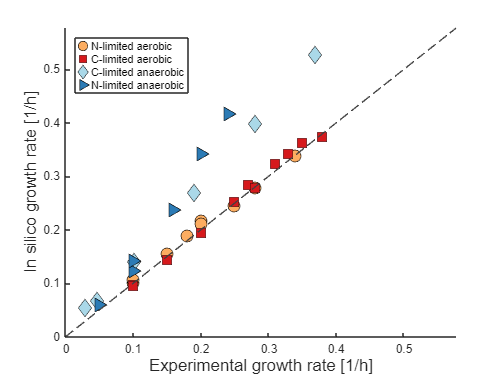

R2 in 9.1.0 model with old anaerobic script: 0.8256


R2old902 = growthOld(model902); fprintf("R2 in 9.1.0 model with old anaerobic script: %.4f\n", R2old902)

### Conclusions from growth curve:

R2 increased from 0.8314 to 0.9077 as a consequence of the new `anaerobicModel` script. The generic curations in 9.1.0 also had a beneficial effect, as repeating the same simulations with the 9.0.2 version of the model gave R2 of 0.8256 and 0.8985 for old and new `anaerobicModel` scripts.

## Convert to anaerobic

Convert all models to anaerobic for second set of model testing.

cd('../otherChanges/')
modelAn = anaerobicModel(model);
modelAnOld = anaerobicModelOld(model);
modelAn902 = anaerobicModel(model902);
modelAnOld902 = anaerobicModelOld(model902);
cd('../modelTests/');

## Run flux prediction tests

In the same order as before, look at the 9.1.0 with new and old `anaerobicModel`, followed by 9.0.2.

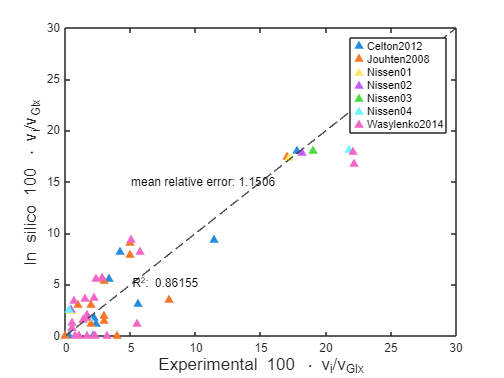

R2fluxnew = anaerobic_flux_predictions(modelAn);

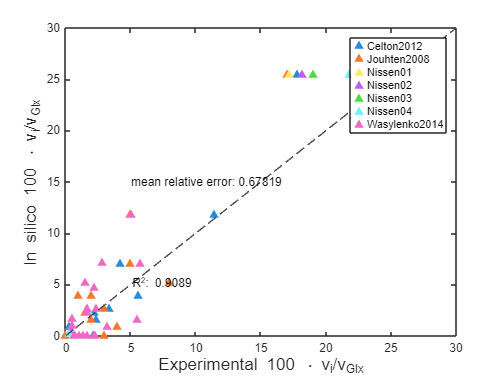

R2fluxold = anaerobic_flux_predictions(modelAnOld);

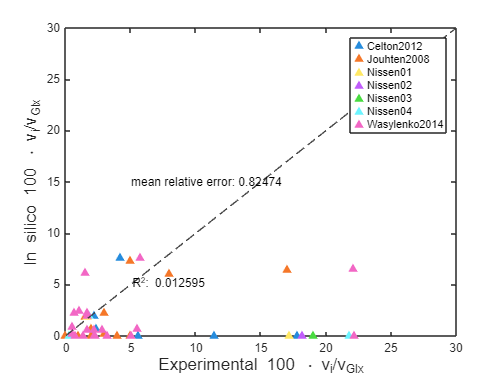

R2fluxnew902 = anaerobic_flux_predictions(modelAn902);

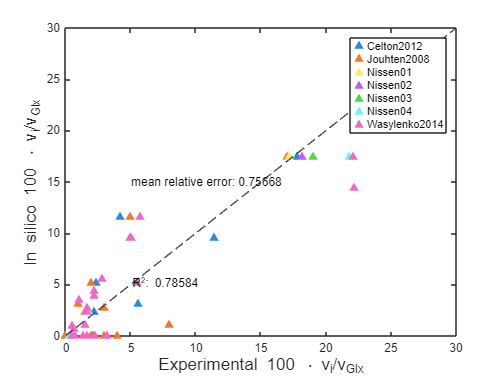

R2fluxold902 = anaerobic_flux_predictions(modelAnOld902);

### Conclusions

R2 increased from 0.8314 to 0.9077 as a consequence of the new anaerobicModel script. The generic curations in 9.1.0 also had a beneficial effect, as repeating the same simulations with the 9.0.2 version of the model gave R2 of 0.8256 and 0.8985 for old and new anaerobicModel scripts.

## Plot

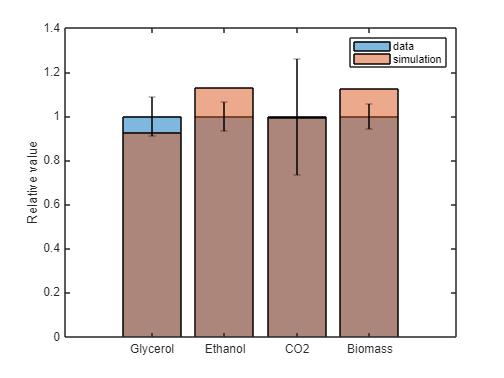

plotAnaerobic(modelAn)

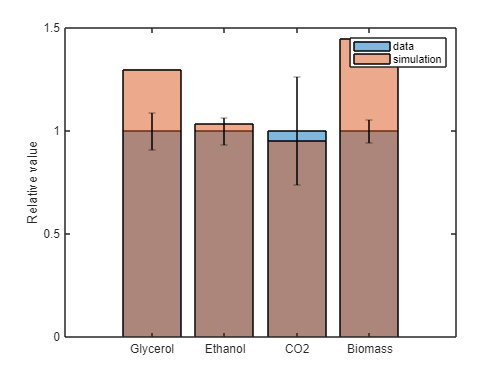

plotAnaerobic(modelAnOld)

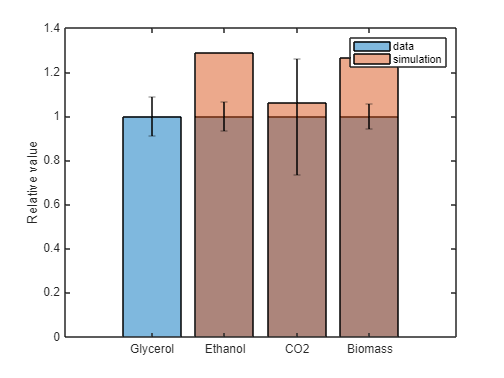

plotAnaerobic(modelAn902)

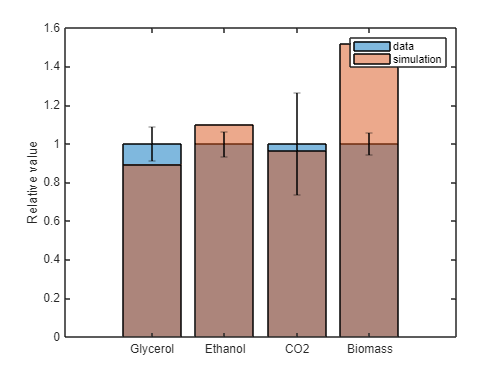

plotAnaerobic(modelAnOld902)

## Set glucose uptake rate and solve pFBA

modelAn = setParam(modelAn,'eq','r_1714',-23);
res=solveLP(modelAn,1);
FLUX = res.x;
v_AStr = res.x(getIndexes(modelAn,'r_1115','rxns'));
v_ATPase = res.x(getIndexes(modelAn,'r_0227','rxns'));
v_glc = res.x(getIndexes(modelAn,'r_1714','rxns'));

## Pack flux results into table

temp_model=modelAn;
rxns_reacs=constructEquations(temp_model,modelAn.rxns);
tab=table(modelAn.rxns,modelAn.rxnNames,rxns_reacs,abs(FLUX./v_glc),FLUX,modelAn.grRules);

[massImbalance, imBalancedMass, imBalancedCharge, imBalancedRxnBool, elements, missingFormulaeBool, balancedMetBool] = checkMassChargeBalance(modelAn);

tabImbalance = [tab,table(imBalancedRxnBool,imBalancedCharge,imBalancedMass)];
tabImbalance(~imBalancedRxnBool,:) = [];
% Filter out exchange and SLIME reactions, these are known to be unbalanced
tabImbalance(contains(tabImbalance.Var2,'exchange'),:) = [];
tabImbalance(contains(tabImbalance.Var2,'SLIME'),:) = [];

## Calculate formula and degree of reduciton of biomass

[mwRange,metFormulae,elements,metEle]=computeMetFormulae(modelAn,'metMwRange','s_0450','fillMets','none','printLevel',0); Biomass_index = find(strcmp(modelAn.metNames,'biomass')); %Degree of reduction per element. Order of the elements 'C', 'H', 'O', 'N' DR_per_ele = [4, 1, -2, -3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]; DR_per_Cmol=sum(metEle(Biomass_index,:).*DR_per_ele)/metEle(Biomass_index,1) Biomass_formula_Cmol=metEle(Biomass_index,:)/metEle(Biomass_index,1); MW_per_Cmol_min = mwRange/metEle(Biomass_index,1)